# Cleanup

clear all
close all
clc

## Parameters

N = 5; % N of photos
gamma = 0.01; % uniform noise coefficient

## Generate cuboid beacon

n_points = 8;
points = [25 25 35 35 25 25 35 35; 25 25 25 25 35 35 35 35; 8 4 8 4 8 4 8 4];
center = mean(points, 2);

## Generate random beacon

n_points = 20; points = 5 * rand(3,n_points) + center;

## Plot beacon features

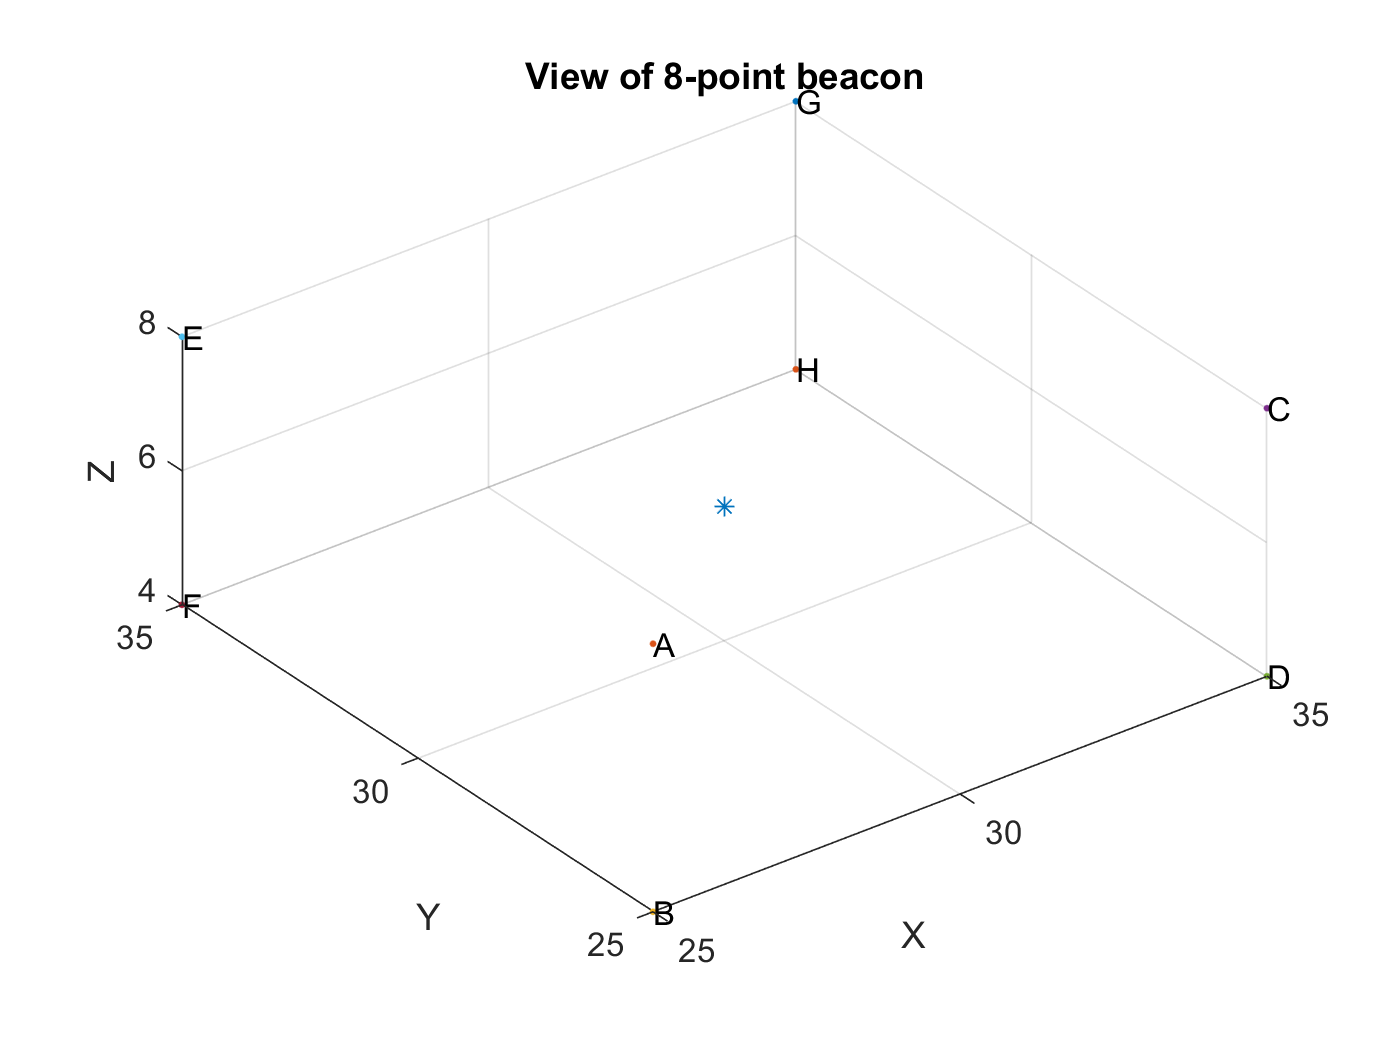

figure('name', 'beacon')
scatter3(center(1), center(2), center(3), 'Marker', '*', 'HandleVisibility','off');
hold on
for  j = 1:n_points
    scatter3(points(1,j), points(2,j), points(3,j) , 'Marker' , '.', 'HandleVisibility','off');
    text(points(1,j), points(2,j), points(3,j), char('@'+ j));
    hold on;
end
title("View of " + n_points + "-point beacon")
axis equal
xlabel 'X'
ylabel 'Y'
zlabel 'Z'

## Trajectory parameters

r0 = 50; % radius of trajectory
x0 = center(1);
y0 = center(2) - r0;
z0 = center(3);
Rwb = [1 0 0; 0 0 1;0 -1 0]; % Initial pose of camera (body 2 word)
Rbw = Rwb'; % Initial pose of camera (word 2 body)
Twb = [x0;y0;z0]; % Initial position of camera
Tbw = -Twb;
alpha = 2 * pi / N; % angle of rotation from each view
Riim1 = axang2rotm([0 1 0 alpha]); % relative rotation between each view

## Initial position

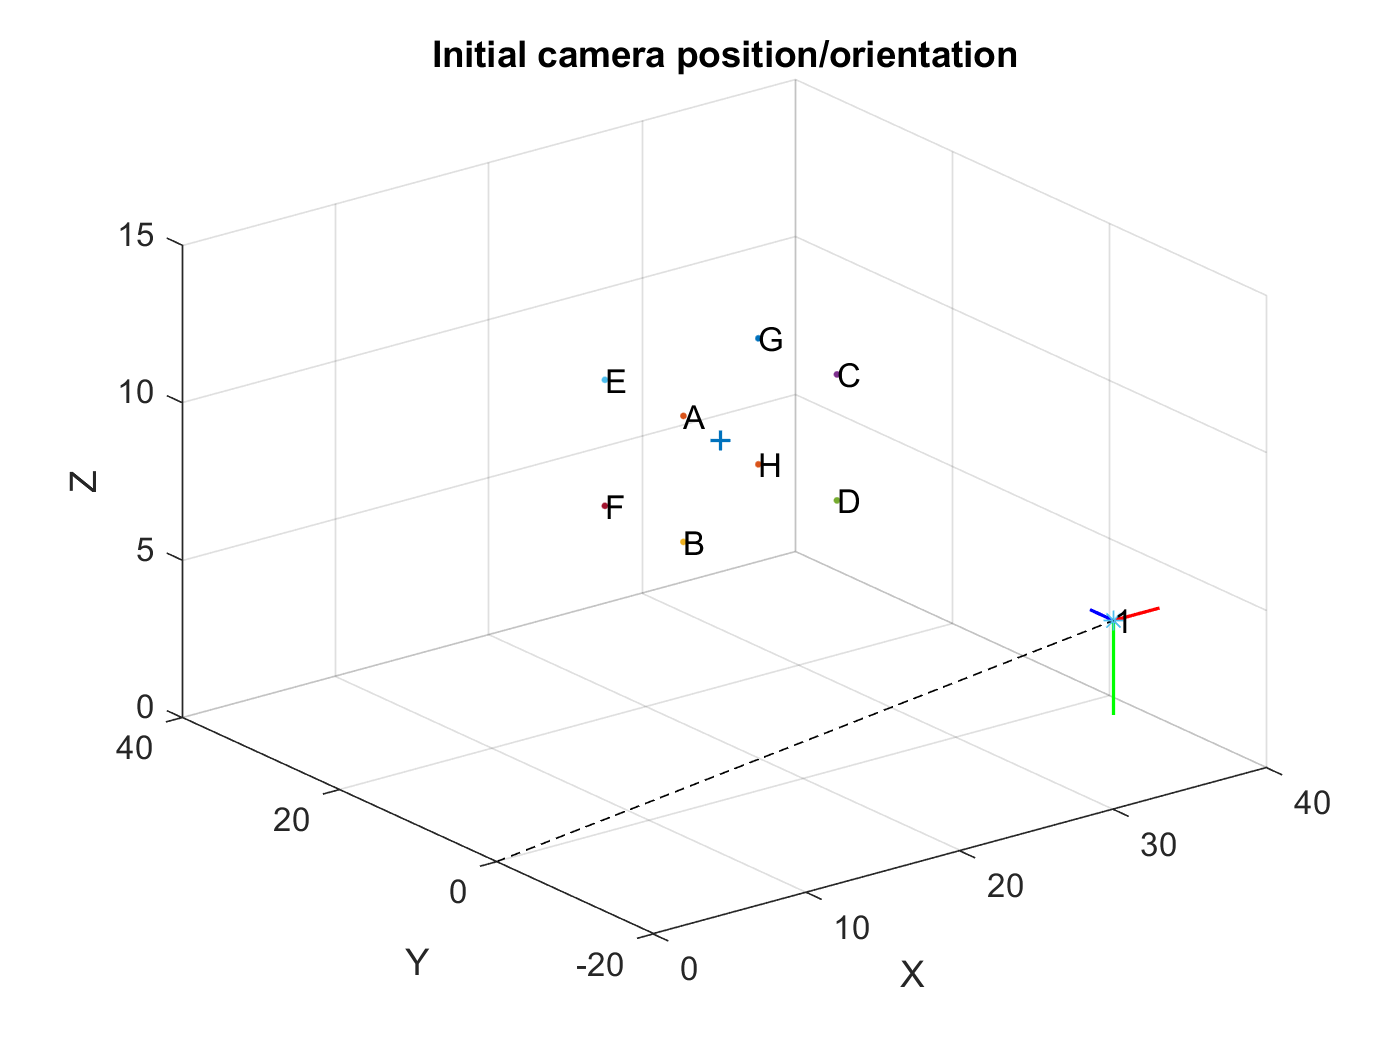

figure
hold on
scatter3(center(1), center(2), center(3), 'Marker' , '+', "LineWidth", 1, "DisplayName", "Center of camera rotation");
for  j = 1:n_points
    scatter3(points(1,j) , points(2,j) , points(3,j) , 'Marker' , '.', 'HandleVisibility','off');
    text(points(1,j), points(2,j), points(3,j), char('@'+ j));
end
triad('Parent',gca,'Scale',3,'LineWidth',1,'Tag','#1','Matrix', [Rwb Twb; 0 0 0 1]);
scatter3(Twb(1), Twb(2), Twb(3), 'Marker',"*", 'HandleVisibility','off')
quiver3(0, 0, 0, Twb(1), Twb(2), Twb(3), "AutoscaleFactor", 1, 'HandleVisibility','off', 'Color', 'k', 'LineStyle','--', "ShowArrowHead", 'off');
text(Twb(1), Twb(2), Twb(3), "1");
view(3)
zlim([0 15])
grid on
xlabel 'X'
ylabel 'Y'
zlabel 'Z'
title("Initial camera position/orientation");

## Trajectory planning, plotting of starting point

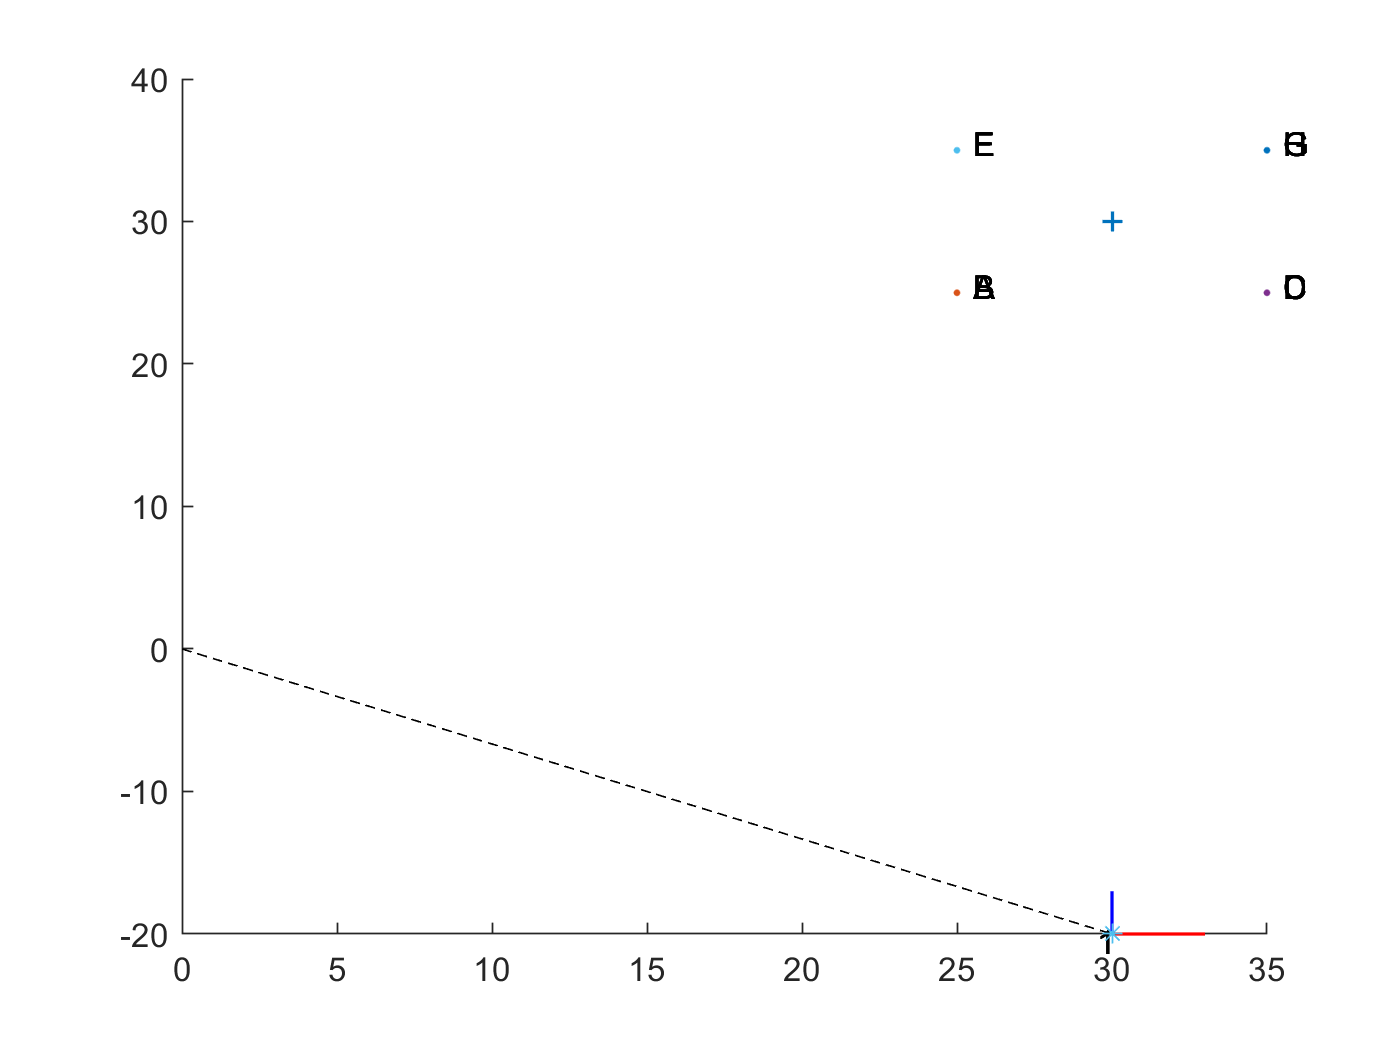

T_history_abs = zeros(3, 1, N);
R_history_abs = zeros(3, 3, N);
R_history_abs(:, :, 1) = Rwb;
T_history_abs(:, :, 1) = Twb;

fig = figure('name', 'trajectory');
hold on
scatter3(center(1), center(2), center(3), 'Marker' , '+', "LineWidth", 1, "DisplayName", "Center of camera rotation");
for  j = 1:n_points
    scatter3(points(1,j) , points(2,j) , points(3,j) , 'Marker' , '.', 'HandleVisibility','off');
    text(points(1,j) + [0.5;0.5;0.5], points(2,j) + [0.5;0.5;0.5], points(3,j) + [0.5;0.5;0.5], char('@'+ j));
end
triad('Parent', gca,'Scale',3,'LineWidth',1,'Tag','#1','Matrix', [Rwb Twb; 0 0 0 1]);
scatter3(Twb(1), Twb(2), Twb(3), 'Marker',"*", 'HandleVisibility','off')
quiver3(0, 0, 0, Twb(1), Twb(2), Twb(3), "AutoscaleFactor", 1, 'HandleVisibility','off', 'Color', 'k', 'LineStyle','--', "ShowArrowHead", 'off');
text(Twb(1) - [0.5 0.5 0.5], Twb(2) - [0.5 0.5 0.5], Twb(3) - [0.5 0.5 0.5], "1");

## Full trajectory generation and plotting

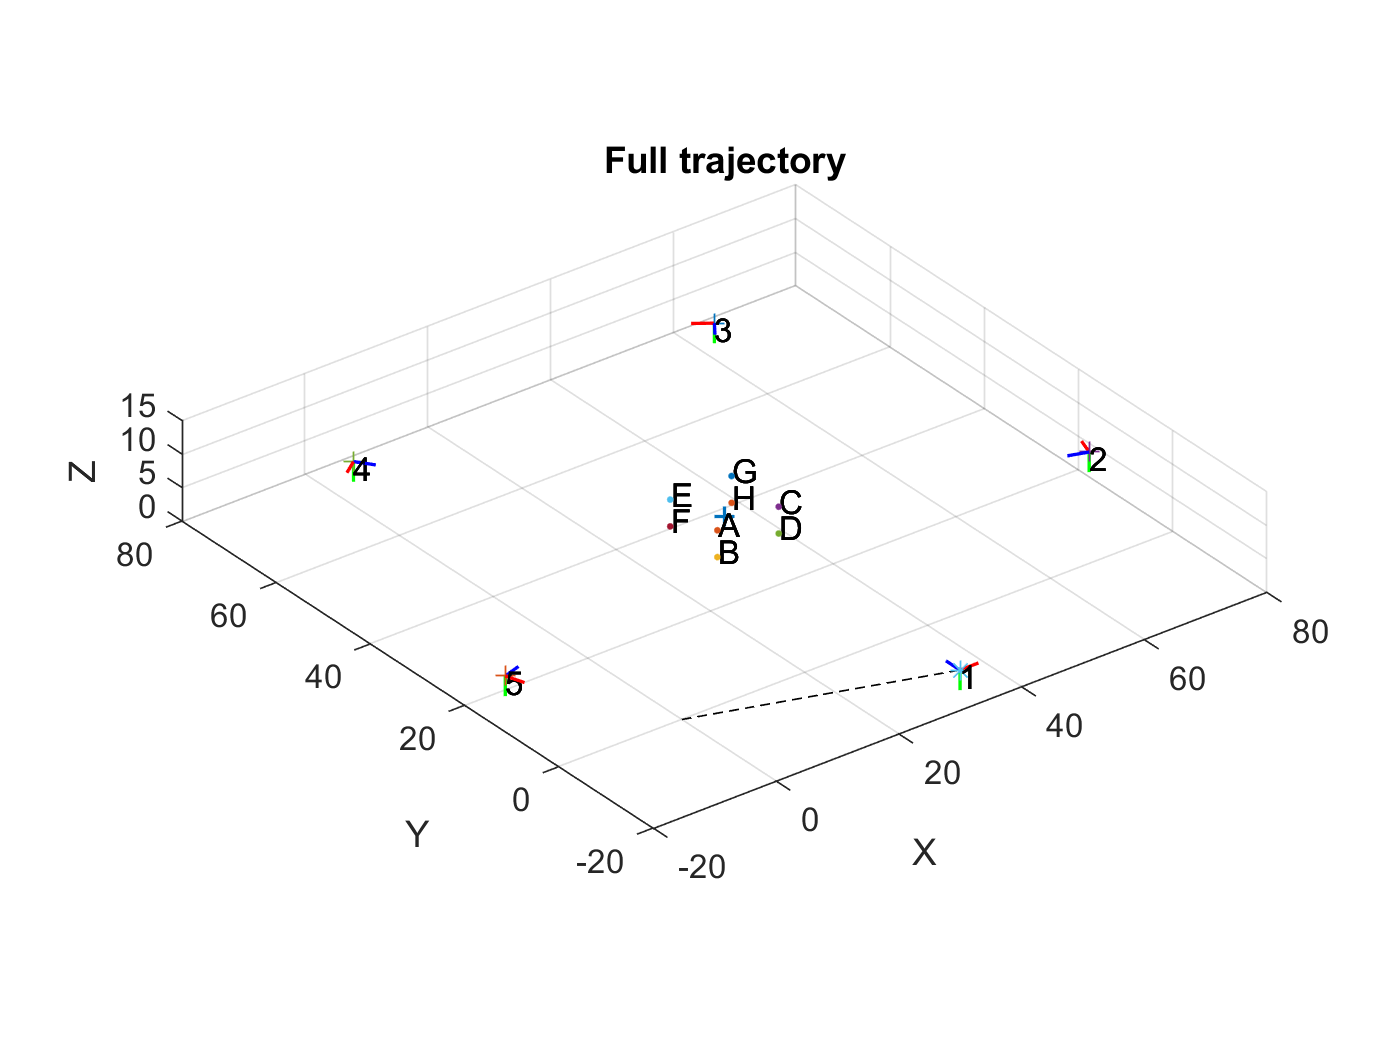

R0im1 = Rwb;
T01 = Twb;
for i = 1:N-1
    R0i = R0im1 * Riim1';
    T0i = T01 + [r0 * sin(alpha * i); r0 * (1 - cos(alpha * i)); 0];
    R0im1 = R0i;
    R_history_abs(:, :, i+1) = R0i;
    T_history_abs(:, :, i+1) = T0i;
    triad('Parent',gca,'Scale',3,'LineWidth',1,'Tag',"#" + (i + 1),'Matrix', [R0i T0i; 0 0 0 1]);
    scatter3(T0i(1) , T0i(2) , T0i(3) , 'Marker' , '+', 'HandleVisibility','off');
    text(T0i(1) - [0.5 0.5 0.5], T0i(2) - [0.5 0.5 0.5], T0i(3) - [0.5 0.5 0.5], "" + (i + 1));
    hold on
end
zlim([0 15])
view(3)
daspect([1 1 1])
grid on
xlabel 'X'
ylabel 'Y'
zlabel 'Z'
title("Full trajectory");

## Trying to compute E matrices from matched points

provato con estimateFundamentalMatrix, non funziona scommentare riga 16, 17 per ottenere un numero soddisfacente di punti in modo che il metodo non dia errore

## Generate E from absolute R and T (until we can figure out projection)

E_history = cell(1,N); % create a cell array equal to the number of poses
EN_history = cell(1,N); % same for noisy E
correct_angles = cell(N,N);
for i = 1:N
    Es = zeros(3,3,N);
    for j = 1:N
        if j == i
            correct_angles(i, j)  = {'X'};
            continue
        elseif j > i 
            R_ij = Riim1'^(j - i);
        else
            R_ij = Riim1^(i - j);
        end
        axang = rotm2axang(R_ij);
        % Check if rotation is around Y axis
        if nnz(abs(axang(1:3)) - [0 1 0] > 1e-3)
            correct_angles(i, j) = {'Non-Y!'};
            continue
        elseif axang(2) < 0
            axang(4) = -axang(4);
        end
        if abs(axang(4)) < 1e-3; axang(4) = 0; end
        correct_angles(i, j)  = {axang(4) * 180 / pi};
        T_ij = T_history_abs(:, j) - T_history_abs(:, i);
        E = getSkew(T_ij) * R_ij;
        Es(:, :, j) = E  ;%/norm(E)% normalize with to lose scale
    end
    E_history(i) = {Es}; % save ideal E matrix
    EN_history(i) = {Es};%{Es + gamma*rand(3, 3)}; % poison E matrix with noise to simulate reconstruction error
end

## Compute R, T from E

R1_rel = cell(N, N);
T1_rel = cell(N, N);
R2_rel = cell(N, N);
T2_rel = cell(N, N);

for i = 1:N
    for j = 1:N

## Compute R_ij and T_ij

        %E = E_history{i}(:,:,j); % Extract E_ij
        E = EN_history{i}(:,:,j); % Uncomment to to use noisy
        [U, S, V] = svd(E); % Singular value decomp
        % Safeguard against non SO(3) matrix
        if (det(U)<0)
            U = [U(:,1) U(:,2) -U(:,3)];
        end
        if (det(V)<0)
            V = [V(:,1) V(:,2) -V(:,3)]; 
        end
        sigmas = diag(S); % Get singular values
        avg = (sigmas(1) + sigmas(2)) / 2; % Average values
        sigmas = [avg; avg; 0]; % Substitute
        S = diag(sigmas);
        Rp = [cos(pi/2) -sin(pi/2) 0; sin(pi/2) cos(pi/2) 0; 0 0 1]; % Rotation of pi/2 around z axis
        Rm = [cos(-pi/2) -sin(-pi/2) 0; sin(-pi/2) cos(-pi/2) 0; 0 0 1]; % Rotation of -pi/2 around z axis
        skewT1 = U * Rp * S * U'; % Get T matrix
        %currT1 = getT(skewT1) % Get T from T matrix
        currT1 = 7.6662 * U(:,3);
        currT2 = -currT1;
        currR1 = U * Rp' * V'; % Get R matrix
        currR2 = U * Rm' * V';
        R1_rel(i,j) = {currR1}; % Save data
        T1_rel(i,j) = {currT1}; %sqrt(norm(currT1))
        R2_rel(i,j) = {currR2};
        T2_rel(i,j) = {currT2};
    end
end

## Perspective projection of points

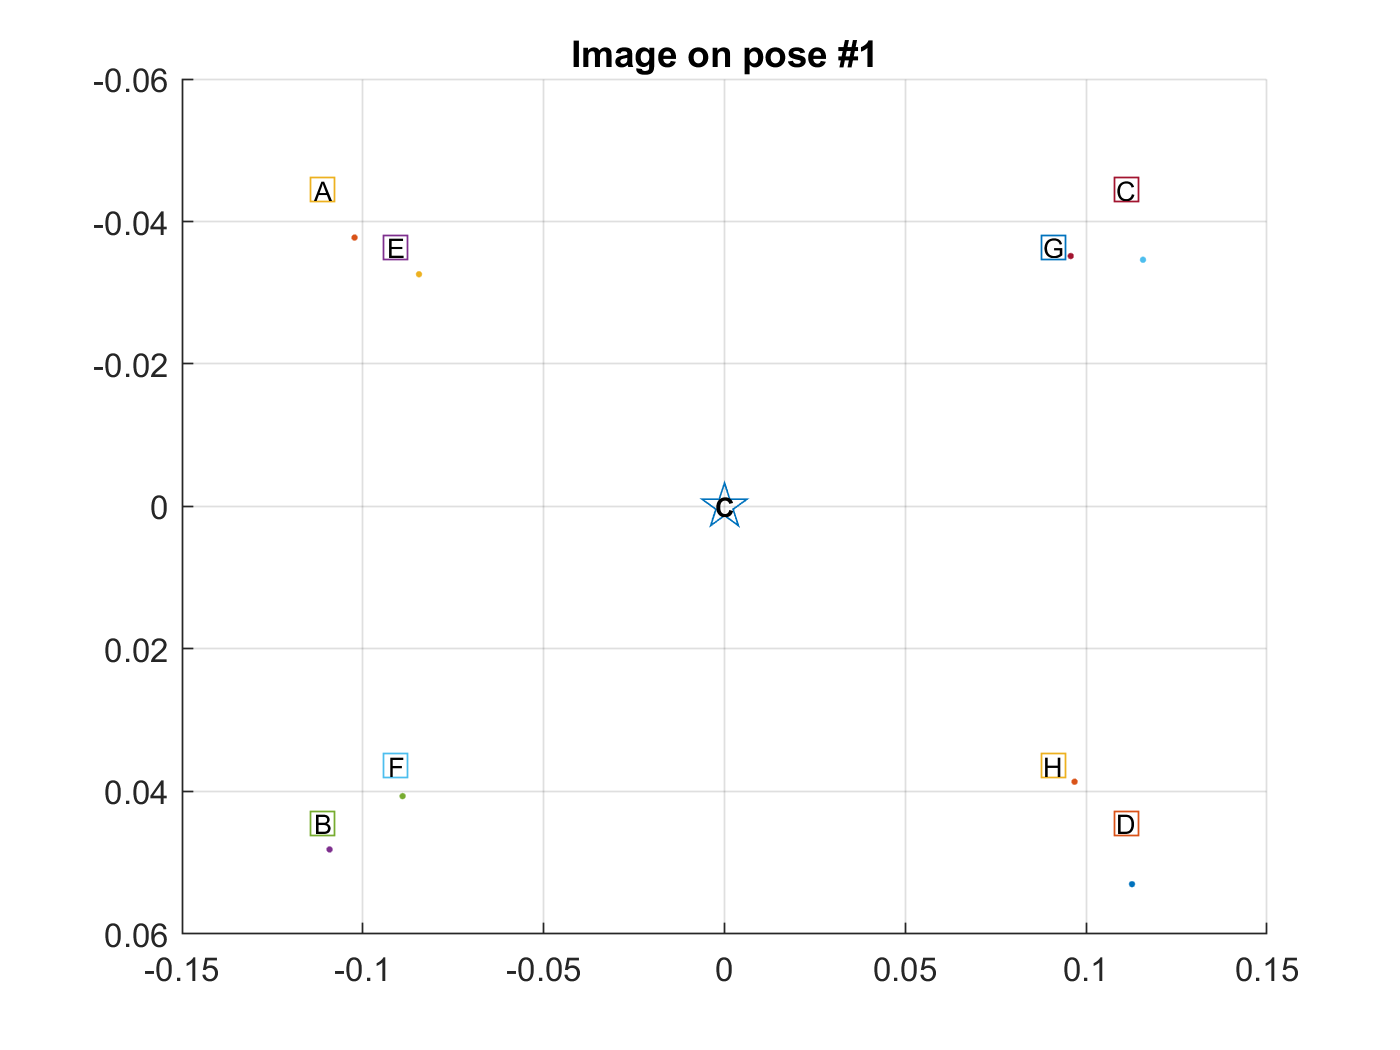

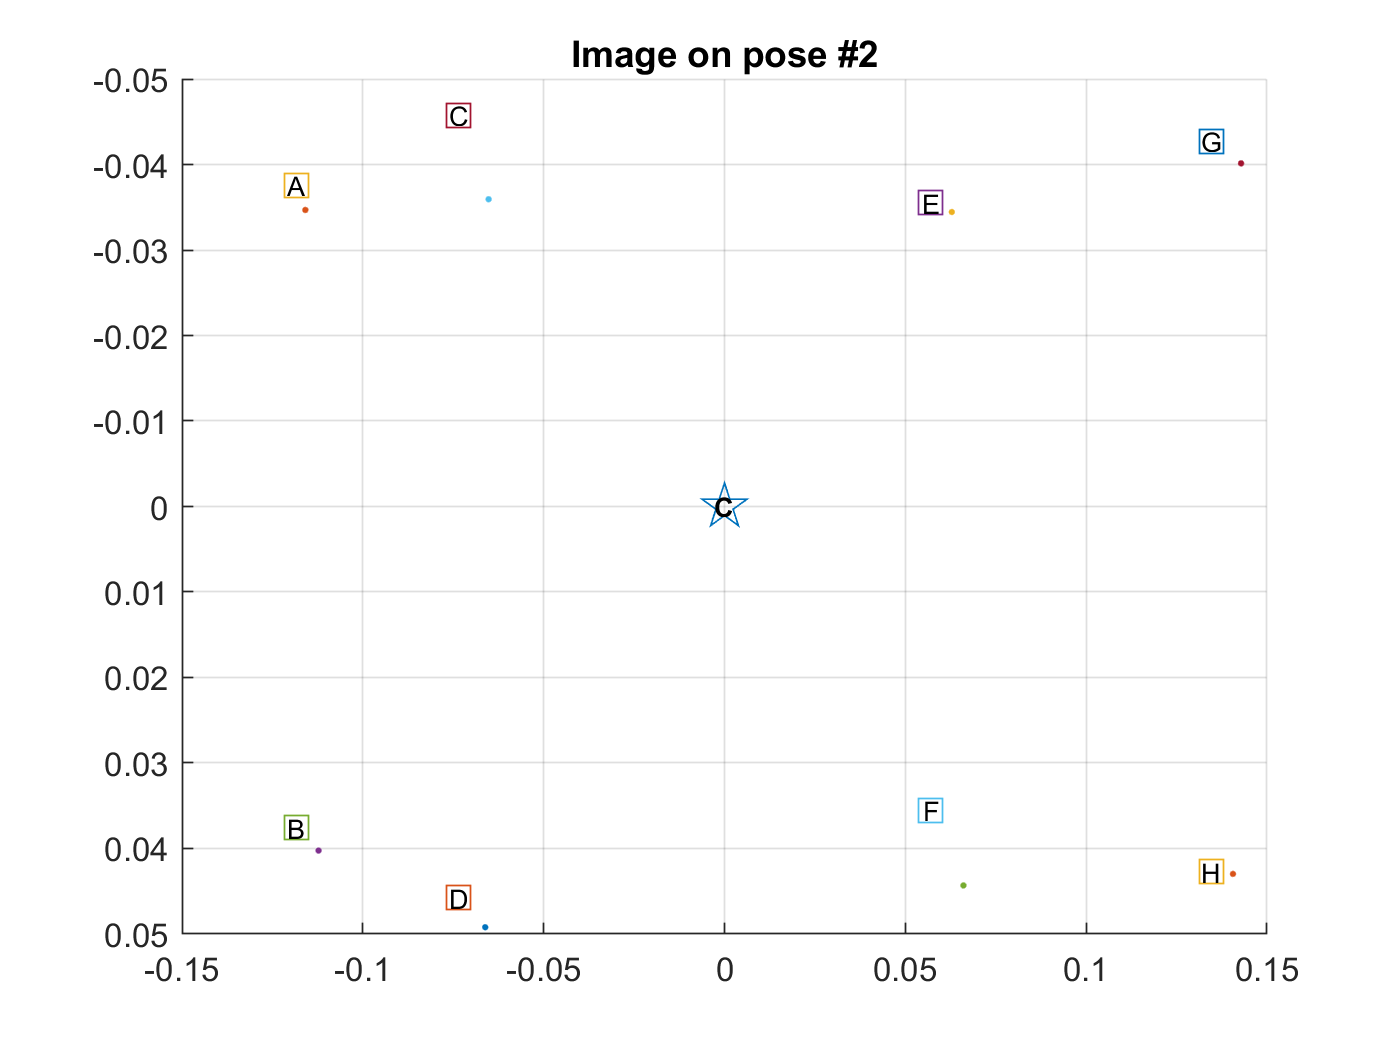

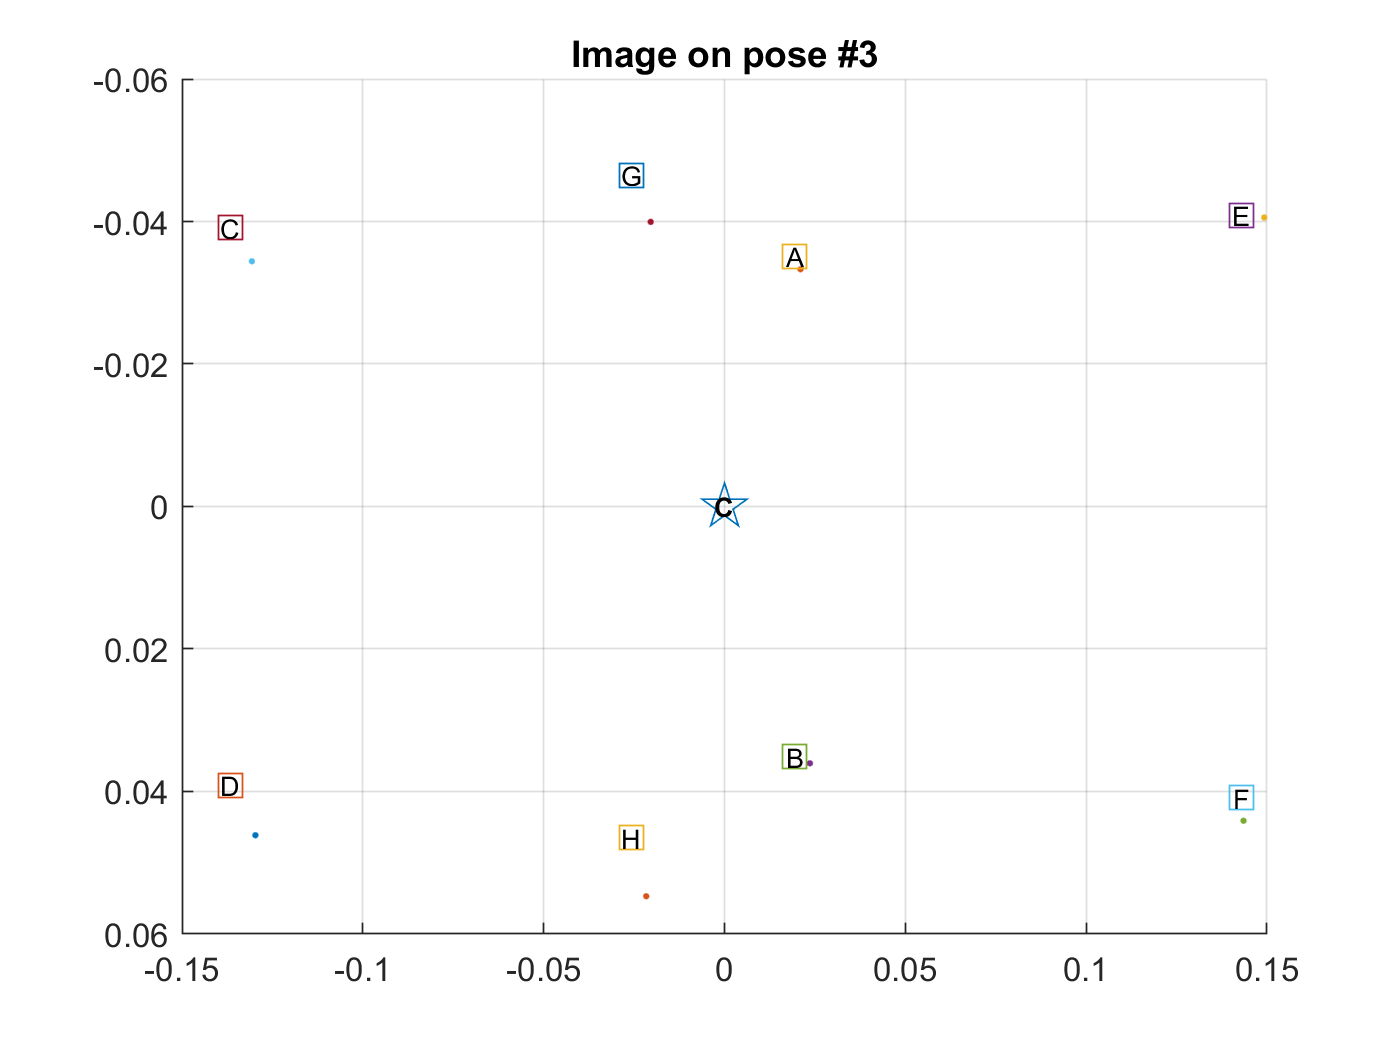

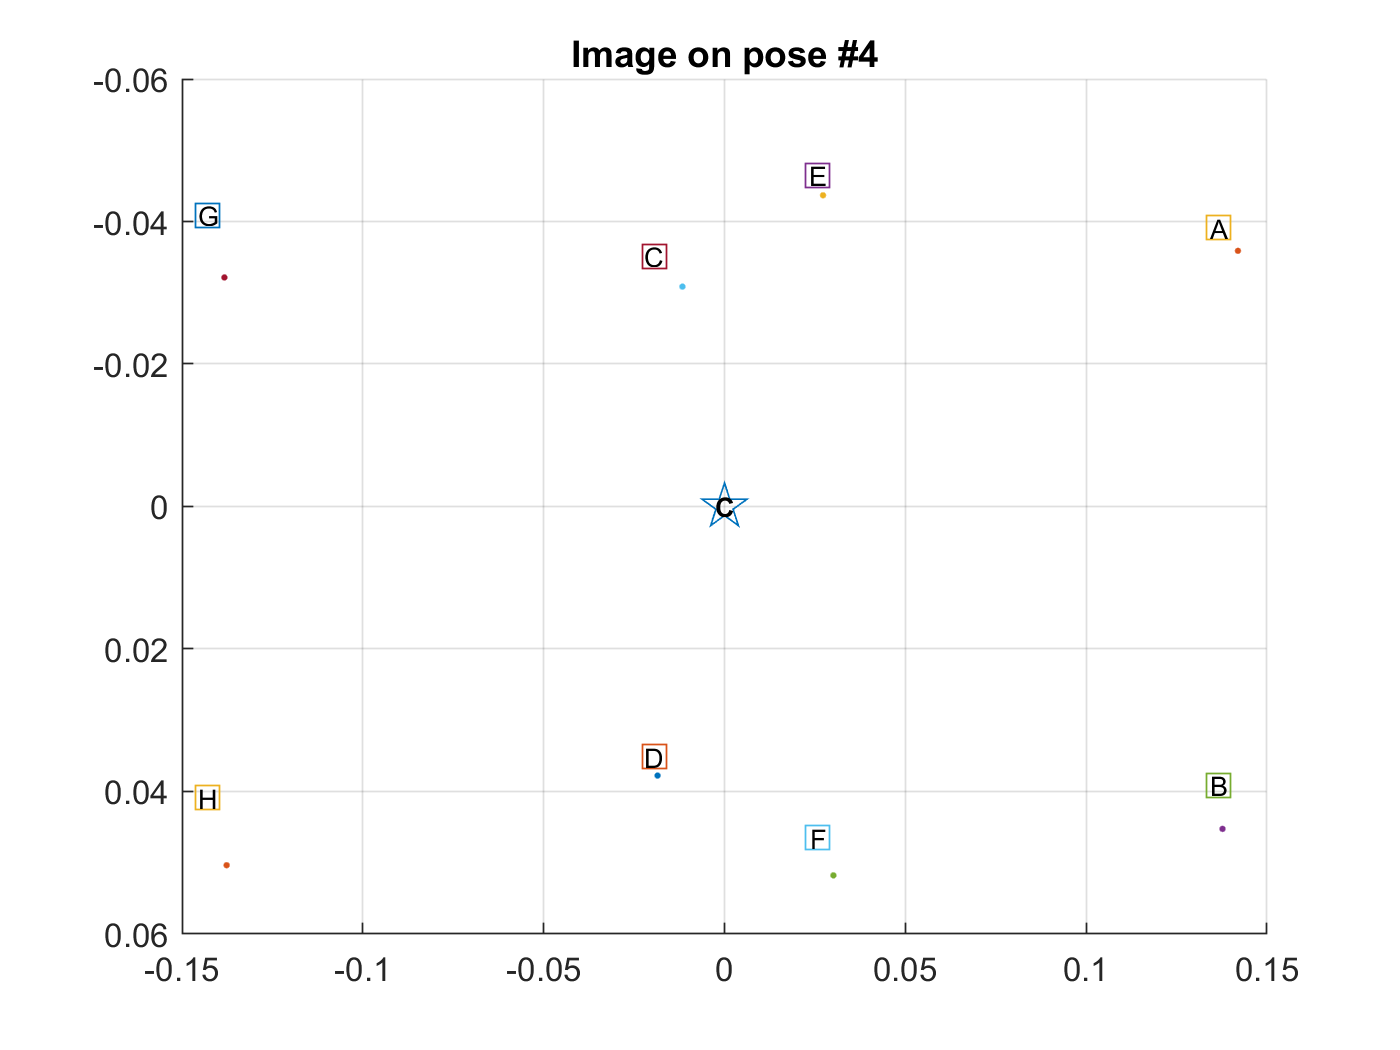

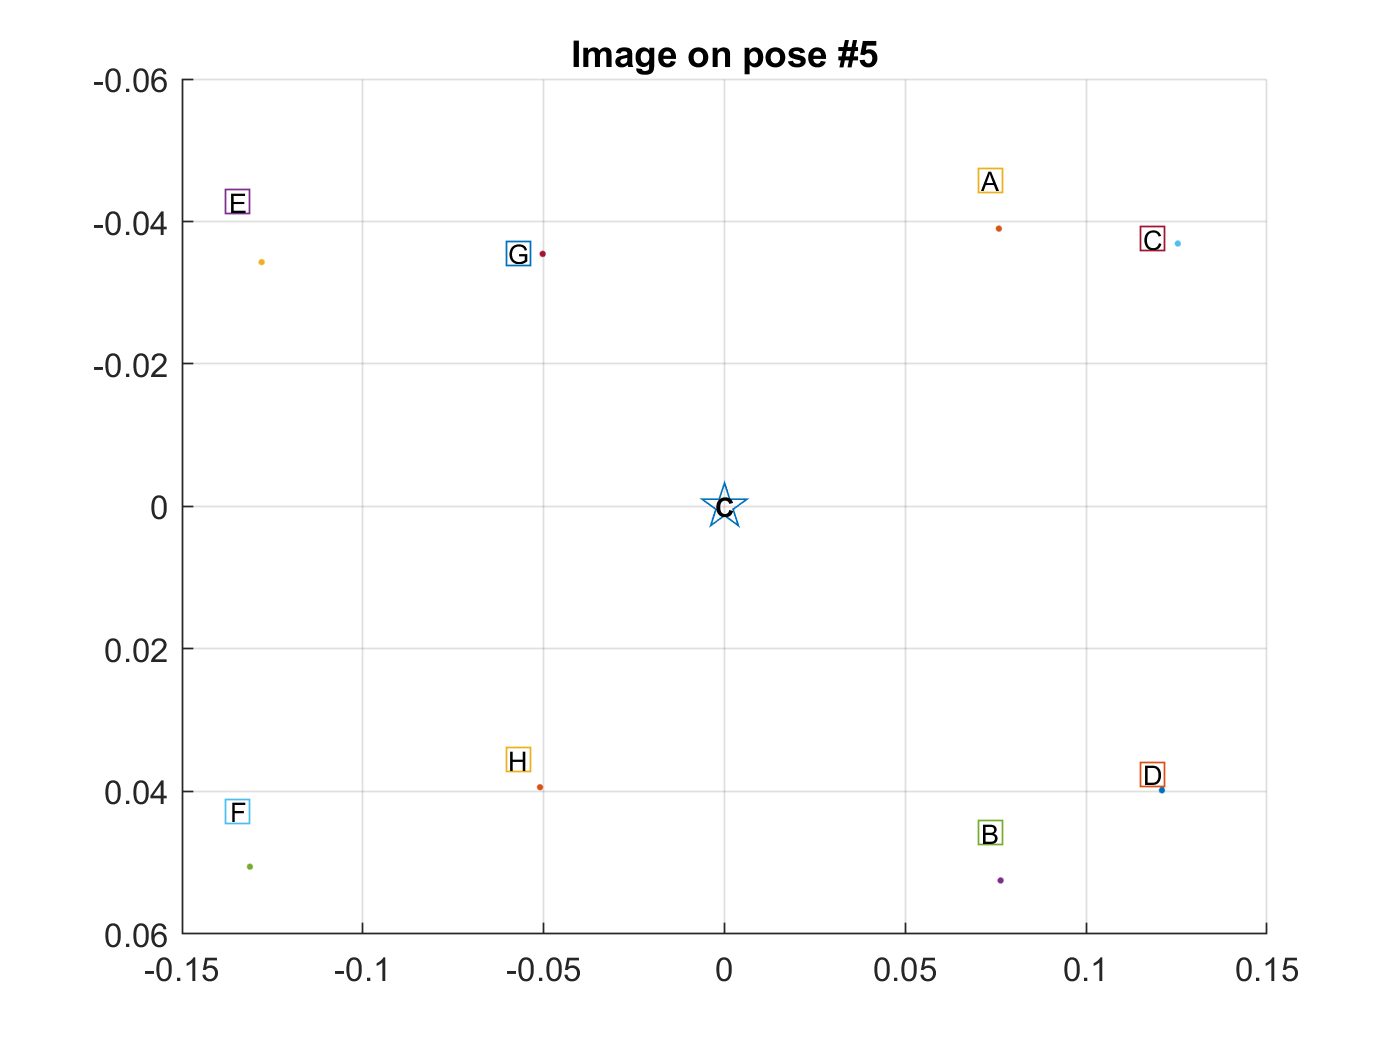

PI0 = [eye(3) zeros(3,1)]; % standard projection matrix
K_f = eye(3); % unitary focal length
K_s = [1 0 0; 0 1 0; 0 0 1]; % ideal, no distortion
K = K_s * K_f;
im_planes_norm = zeros(3, n_points, N);% normalized points for each view
im_planes_noisy = zeros(3, n_points, N);% noisy points for each view (photos)
centers_norm = zeros(3, N);
centers_noisy = zeros(3,N);

for i = 1:N
    figure('name', "photo" + i);
    R0i = R_history_abs(:, :, i);
    T0i = T_history_abs(:, :, i);
    Ri0 = R0i';
    Ti0 = -T0i;
    g = [Ri0 Ri0*Ti0; 0 0 0 1];
    proj_c_og = K * PI0 * g * [center; 1];
    proj_c_norm = proj_c_og / proj_c_og(3);
    centers_norm(:, i) = proj_c_norm;
    centers_noisy(:, i) = proj_c_norm + [gamma*rand(2,1); 0];
    scatter(proj_c_norm(1), proj_c_norm(2), 200, "Marker", "pentagram");
    text(proj_c_norm(1), proj_c_norm(2), "C", "Fontsize", 8, "HorizontalAlignment","center","FontWeight","bold");
    hold on
    grid on
    for j = 1:n_points
        im_point = K * PI0 * g * [points(:,j); 1];
        im_planes_norm(:, j, i) = im_point / im_point(3);
        im_planes_noisy(:, j, i) = im_point / im_point(3) + [gamma*rand(2,1); 0];
        scatter(im_planes_noisy(1, j, i), im_planes_noisy(2, j, i), 36, "Marker", ".");
        scatter(im_planes_norm(1, j, i), im_planes_norm(2, j, i), 90, "Marker", "square");
        text(im_planes_norm(1, j, i), im_planes_norm(2, j, i), char('@'+ j), "Fontsize", 8, "HorizontalAlignment","center");
    end
    title("Image on pose #" + i);
    set(gca, 'YDir','reverse')
end

## Trying to triangulate (for each subsequent frame) points from images in order to discriminate pose

cam = cameraParameters("IntrinsicMatrix", K);
R_rel = cell(N,N);
T_rel = cell(N,N);

R1_rel; %rad2deg(rotm2eul(R1_rel{1,2}))
R2_rel; %rad2deg(rotm2eul(R2_rel{1,2}))
T1_rel; %T1_rel{1,2}
T2_rel; %T2_rel{1,2} the reverse of the previous


for i=2:N
        
        % Extract R12 and T12 matrices
        R = R1_rel{i,i-1}; %pose of i relative to i-1
        T = T1_rel{i,i-1};
        
        R_rel{i,i-1} = R;
        T_rel{i,i-1} = T;
        
        % Configure foward extrinsic
        sParams = stereoParameters(cam, cam, R, T);   %(R, -T) and (R' , -T) are OK
        % Triangulate points in frame 1
        pnts1 = (triangulate(centers_noisy(1:2,i-1)', centers_noisy(1:2,i)', sParams)); %points expressed wrt the reference frame of camera i-1
        sParams = stereoParameters(cam, cam, R', -R' * T);
        pnts2 = (triangulate(centers_noisy(1:2,i)', centers_noisy(1:2,i-1)', sParams));
         
        if(pnts1(3) > 0 && pnts2(3) > 0)
           R_rel{i,i-1} = R;
           T_rel{i,i-1} = T;
        end
        
        
        
        % Extract R12 and T12 matrices
        R = R2_rel{i,i-1}; %pose of i relative to i-1
        T = T1_rel{i,i-1};
        
        % Configure foward extrinsic
        sParams = stereoParameters(cam, cam, R, T);   %(R, -T) and (R' , -T) are OK
        % Triangulate points in frame 1
        pnts1 = (triangulate(centers_noisy(1:2,i-1)', centers_noisy(1:2,i)', sParams)); %points expressed wrt the reference frame of camera i-1
        sParams = stereoParameters(cam, cam, R', -R' * T);
        pnts2 = (triangulate(centers_noisy(1:2,i)', centers_noisy(1:2,i-1)', sParams));
         
        if(pnts1(3) > 0 && pnts2(3) > 0)
           R_rel{i,i-1} = R;
           T_rel{i,i-1} = T;
        end
        
        
        % Extract R12 and T12 matrices
        R = R1_rel{i,i-1}; %pose of i relative to i-1
        T = T2_rel{i,i-1};
        
        % Configure foward extrinsic
        sParams = stereoParameters(cam, cam, R, T);   %(R, -T) and (R' , -T) are OK
        % Triangulate points in frame 1
        pnts1 = (triangulate(centers_noisy(1:2,i-1)', centers_noisy(1:2,i)', sParams)); %points expressed wrt the reference frame of camera i-1
        sParams = stereoParameters(cam, cam, R', -R' * T);
        pnts2 = (triangulate(centers_noisy(1:2,i)', centers_noisy(1:2,i-1)', sParams));
         
        if(pnts1(3) > 0 && pnts2(3) > 0)
           R_rel{i,i-1} = R;
           T_rel{i,i-1} = T;
        end
        
        
        % Extract R12 and T12 matrices
        R = R2_rel{i,i-1}; %pose of i relative to i-1
        T = T2_rel{i,i-1};
        
        % Configure foward extrinsic
        sParams = stereoParameters(cam, cam, R, T);   %(R, -T) and (R' , -T) are OK
        % Triangulate points in frame 1
        pnts1 = (triangulate(centers_noisy(1:2,i-1)', centers_noisy(1:2,i)', sParams)); %points expressed wrt the reference frame of camera i-1
        sParams = stereoParameters(cam, cam, R', -R' * T);
        pnts2 = (triangulate(centers_noisy(1:2,i)', centers_noisy(1:2,i-1)', sParams));
         
        if(pnts1(3) > 0 && pnts2(3) > 0)
           R_rel{i,i-1} = R;
           T_rel{i,i-1} = T;
        end
        
        
        if T_rel{i,i-1}(1) < 0
          T_rel{i,i-1} = - T_rel{i,i-1}
        end
end



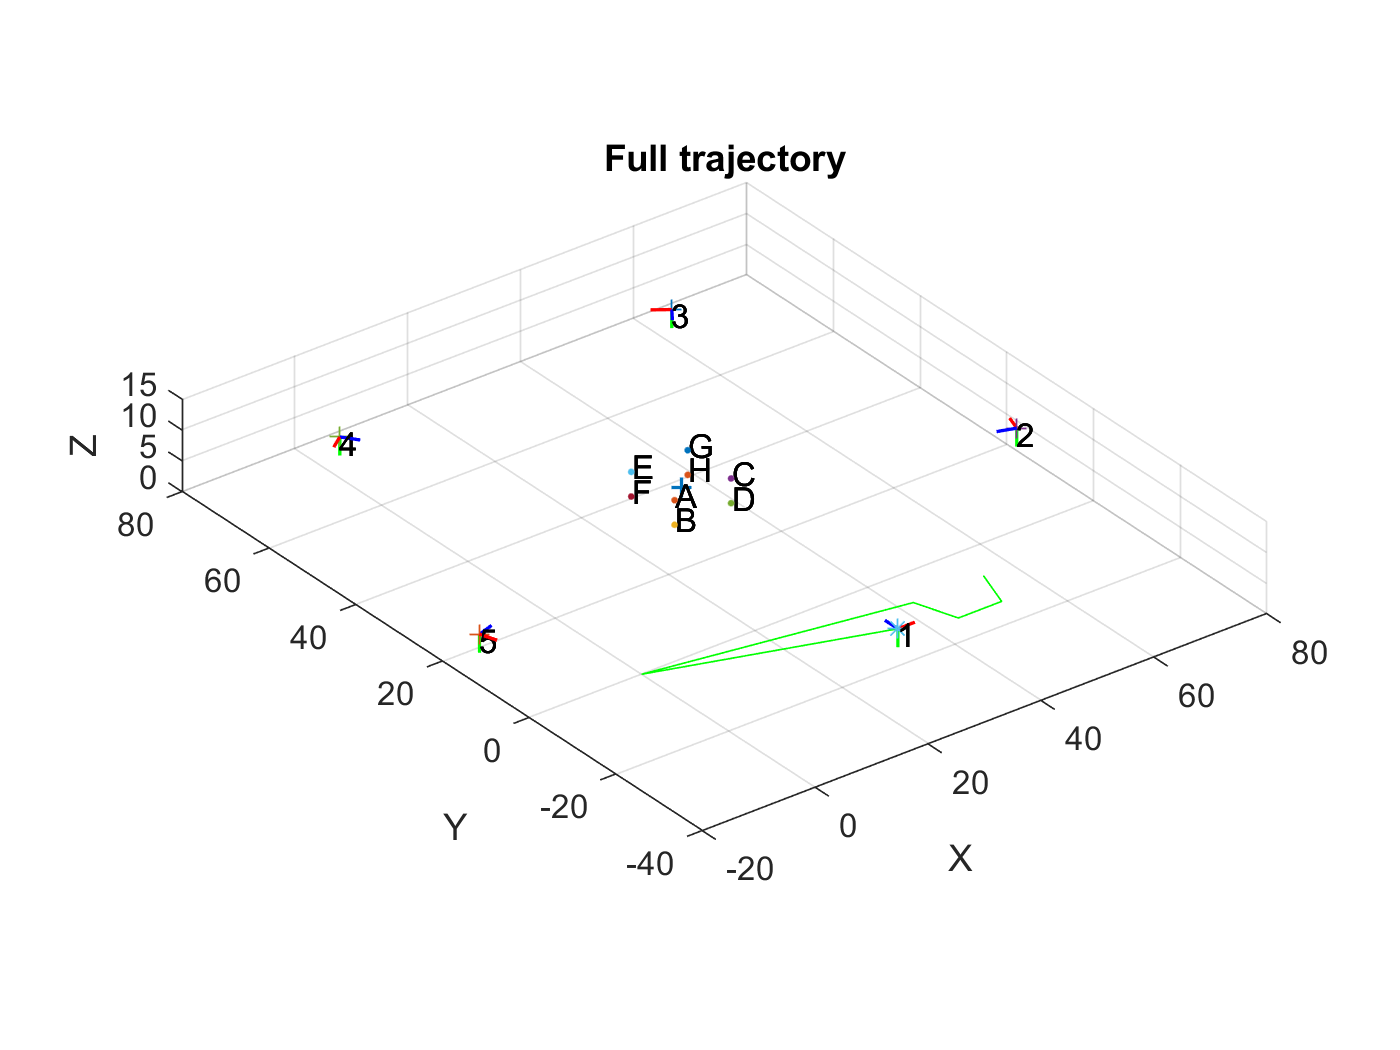

%% Translations
currP = Twb;
traj = zeros(3, N + 1);
traj(:,1) = Twb;
for i = 2:N
    nextP = currP + T_rel{i,i-1};
    traj(:, i + 1) = nextP;
    currP = nextP;
end
figure(fig)
set(0,'CurrentFigure',fig)
hold on
plot3(traj(1, :), traj(2, :), traj(3, :), "DisplayName", "Reconstructed trajectory final", "Color", "g")
view(3)